read

filename = "viola2"

filename = "viola2"

filepath_s = "./data/" + filename + "_HPR_S.wav";
[s, fs] = audioread(filepath_s);
s = highpass(s, 30, fs);
filepath_n = "./data/" + filename + "_HPR_N.wav";
[n, fs] = audioread(filepath_n);
filepath_t = "./data/" + filename + "_HPR_T.wav";
[t, fs] = audioread(filepath_t);

%sound(s(1:fs*2), fs); pause(2.5)
duration = length(s) / fs;

まずWSOLA

tWR = wsolaTSM(resample(t, 2, 1), 0.5);
sWR = lowpass(wsolaTSM(resample(s, 2, 1), 0.5), fs/4, fs);
snWR = lowpass(wsolaTSM(resample(s+n, 2,1), 0.5), fs/4, fs);
nWR = wsolaTSM(resample(n,2,1),0.5);

% transient のみOLAが機能する可能性を持つ
paramOLA.tolerance = 0;
paramOLA.synHop = 256;
paramOLA.win = win(512,2); % hann window
tOLA = wsolaTSM(resample(t, 2, 1), 0.5, paramOLA);

それぞれ聞いてみる

sound(snWR+tOLA, fs); pause(duration)

わるくないかも

nbi = shiftPitch(n, -12);
nbi_pl = shiftPitch(n, -12, "Window", sqrt(hann(1024, "periodic")), "LockPhase", true);
sbi = highpass(shiftPitch(s, -12), 30,fs);
snbi = shiftPitch(s+n, -12);
tbi = shiftPitch(t, -12, "LockPhase",true);
soundsc(snbi+tbi  , fs); pause(duration)

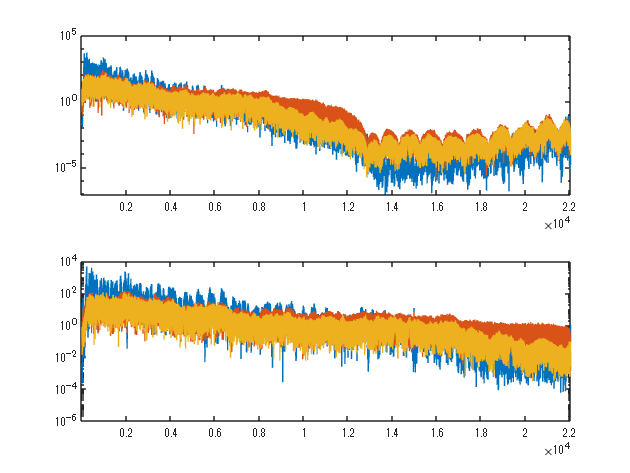

%% 重音でなければWSOLAが使える．（STNがうまくいっていれば重音でもいいはずだけど）
soundsc(sbi+nWR+tOLA,fs); pause(duration)
figure;
tiledlayout(2,1)
nexttile
axisFreq = (0:length(s)-1)/length(s)*fs;
semilogy(axisFreq, abs(fft(sbi))); 
hold on; 
semilogy(axisFreq, abs(fft(nWR))); 
semilogy(axisFreq, abs(fft(tOLA)))
xlim([1,fs/2])

nexttile
semilogy(axisFreq, abs(fft(s))); 
hold on; 
semilogy(axisFreq, abs(fft(n))); 
semilogy(axisFreq, abs(fft(t)))
xlim([1,fs/2])

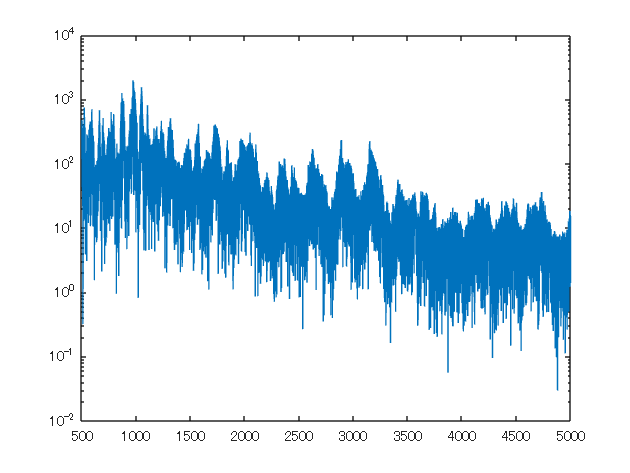

%sWR_harm = highpass(SoftClipper(lowpass(sWR, fs/4, fs, "steepness", 0.6)*1), 10000, fs, "steepness", 0.6);
sbi_found = lowpass(sbi, 400, fs, "steepness", 0.5);
sbi_harm = highpass(SoftClipper(sbi_found*2)*0.5+0.4*abs(sbi_found), 8000, fs, "steepness", 0.5);
nmix = nWR;%  + highpass(n,fs/4,fs,"Steepness",0.5);
tmix = tOLA;% + highpass(t,fs/4,fs,"Steepness",0.5);
org_high = highpass(s+n+t, fs/4, fs);
soundsc(sbi + sbi_harm  + nmix + tmix + 0.2*org_high, fs)
%    highpass(tOLA + 0.3*abs(tOLA),30,fs), fs);
figure
semilogy(axisFreq, abs(fft(sbi + sbi_harm  + nmix + tmix + 0.2*org_high)));
xlim([500,5000])

これもわるくない

% %% setting parameters
% parameter.pvSynHop = 512;
% parameter.pvWin = win(2048,2); % hann
% parameter.pvZeroPad = 0;
% parameter.pvRestoreEnergy = 0;
% parameter.pvFftShift = 0;
% parPv.synHop = parameter.pvSynHop;
% parPv.win = parameter.pvWin;
% parPv.zeroPad = parameter.pvZeroPad;
% parPv.restoreEnergy = parameter.pvRestoreEnergy;
% parPv.fftShift = parameter.pvFftShift;
% parPv.phaseLocking = 1;
% 
% %% phase vocoder with phase locking
% sPvR = pvTSM(resample(s, 2, 1), 0.5, parPv);
% hPvR = pvTSM(resample(h, 2, 1), 0.5, parPv);
% mixPvR = pPvR + hPvR;
% 
% %% sound them
% sound(pPvR(1:2*fs), fs);  pause(3)
% sound(hPvR(1:2*fs), fs); pause(3)
% sound(mixPvR, fs);